# Simulations

## First order SDT

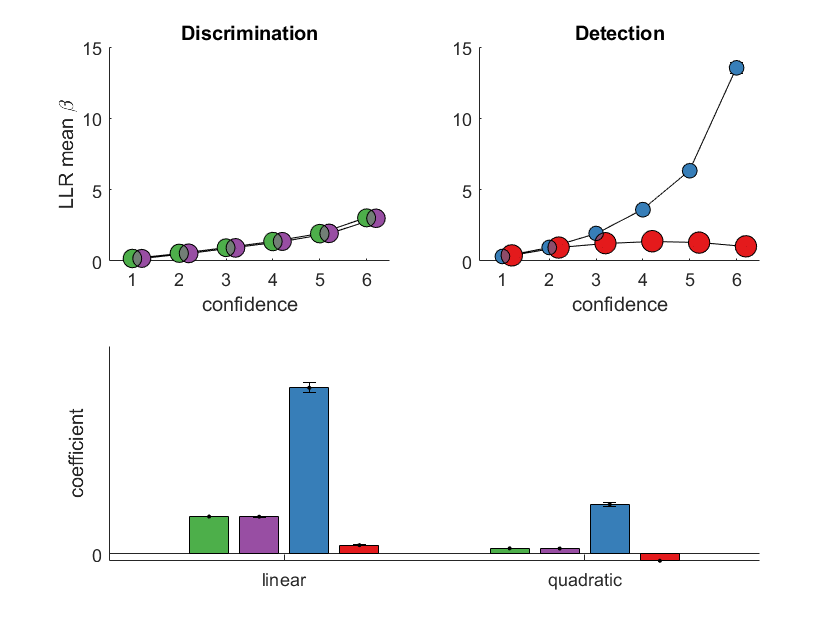

trial_count.C_num_trials = [];
trial_count.A_num_trials = [];
simulation_betas.conf_A = [];
simulation_betas.conf_C = [];

trial_count.Y_num_trials = [];
trial_count.N_num_trials = [];
simulation_betas.conf_Y = [];
simulation_betas.conf_N = [];

for i_s = 1:35
    %discrimination
    dis.mu = binornd(1,0.5,200,1)-0.5;
    dis.samples = normrnd(dis.mu,1);
    dis.likelihood1 = normpdf(dis.samples,-0.5,1);
    dis.likelihood2 = normpdf(dis.samples,0.5,1);
    dis.LLR = log2(dis.likelihood1./dis.likelihood2);
    dis.resp = dis.samples>0;
    dis.edges  = prctile(abs(dis.samples),100/6*[0:6]);
    dis.conf = discretize(abs(dis.samples),dis.edges);
    for i_conf = 1:6
        trial_count.C_num_trials(i_s,i_conf) = ...
            sum(dis.conf==i_conf & dis.resp==0);
        trial_count.A_num_trials(i_s,i_conf) = ...
            sum(dis.conf==i_conf & dis.resp==1);
        simulation_betas.conf_C(i_s,i_conf) = ...
            nanmean(abs(dis.LLR(dis.conf==i_conf & dis.resp==0)));
        simulation_betas.conf_A(i_s,i_conf) = ...
            nanmean(abs(dis.LLR(dis.conf==i_conf & dis.resp==1)));
    end
    
     %detection
    det.mu = binornd(1,0.5,200,1);
    det.samples = normrnd(det.mu*1.3,(1+det.mu)); %unequal variance
    det.likelihood1 = normpdf(det.samples,1.3,2);
    det.likelihood2 = normpdf(det.samples,0,1);
    det.LLR = log2(det.likelihood1./det.likelihood2);
    det.resp = det.samples>1.2;
    det.yes_edges  = prctile(det.samples(det.resp),100/6*[0:6]);
    det.conf = discretize(det.samples,det.yes_edges);
    det.no_edges  = prctile(-det.samples(~det.resp),100/6*[0:6]);
    det.conf(~det.resp) = discretize(-det.samples(~det.resp),det.no_edges);
    for i_conf = 1:6
        trial_count.N_num_trials(i_s,i_conf) = ...
            sum(det.conf==i_conf & det.resp==0);
        trial_count.Y_num_trials(i_s,i_conf) = ...
            sum(det.conf==i_conf & det.resp==1);
        simulation_betas.conf_N(i_s,i_conf) = ...
            nanmean(abs(det.LLR(det.conf==i_conf & det.resp==0)));
        simulation_betas.conf_Y(i_s,i_conf) = ...
            nanmean(abs(det.LLR(det.conf==i_conf & det.resp==1)));
    end
    
end
simulation_name = 'LLR';
plotQuadFit(trial_count, simulation_betas,simulation_name);